% Update this string with the name of your actual audio file
filename = "C:\Users\user\Downloads\mixkit-musical-alert-notification-2309.wav"; 

% Read the audio file
% 'Gs' is the amplitude data, 'Fsg' is the sampling frequency (Hz)
[Gs, Fsg] = audioread(filename);

% Convert Stereo to Mono (if necessary)
if size(Gs, 2) > 1
    Gs = mean(Gs, 2);
end

% Calculating the number of samples in Guitar
NG = length(Gs);

% Calculating the time of the instrument
% Since Fsg is frequency, 1/Fsg is the sampling period (dt)
TG = NG * (1/Fsg);

fprintf('Length of Guitar recording: %.4f seconds\n', TG);

Length of Guitar recording: 1.4260 seconds


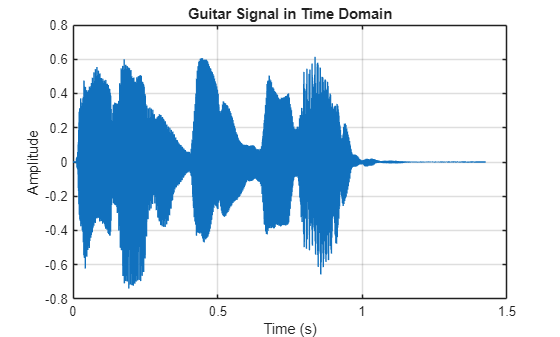


%% Part 2: Frequency Content Analysis

% Plotting the signals in Time Domain
figure('Name', 'Time Domain Signals');
plot((0:NG-1) * (1/Fsg), Gs);
title('Guitar Signal in Time Domain');
xlabel('Time (s)'); ylabel('Amplitude'); grid on;

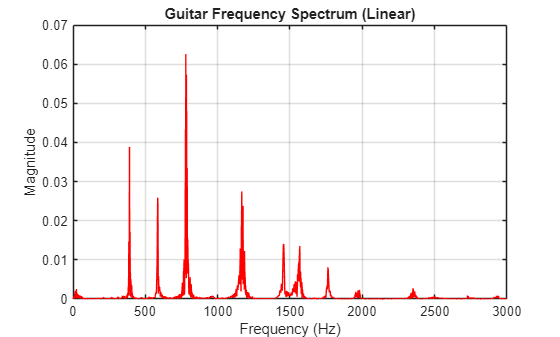


% --- Guitar FFT ---
% Fsg is ALREADY the sampling frequency in Hz, no need to invert it!

% Creating a frequency vector for x axis 
f_G = Fsg * (0:floor(NG/2)) / NG;

% Computing FFT (Fast Fourier Transform)
Y_G = fft(Gs);               

% Normalizing the signal and considering magnitude of the signal
P2_G = abs(Y_G / NG);           

% Converting the two sided signal into a single sided signal
P1_G = P2_G(1:floor(NG/2)+1);          
P1_G(2:end-1) = 2 * P1_G(2:end-1); 


% --- Plotting Guitar (Linear & Logarithmic) ---
figure('Name', 'Guitar Frequency Spectrum');
plot(f_G, P1_G, 'r');
title('Guitar Frequency Spectrum (Linear)');
xlabel('Frequency (Hz)'); ylabel('Magnitude');
xlim([0 3000]); % Zoom in to see the peaks clearly
grid on;

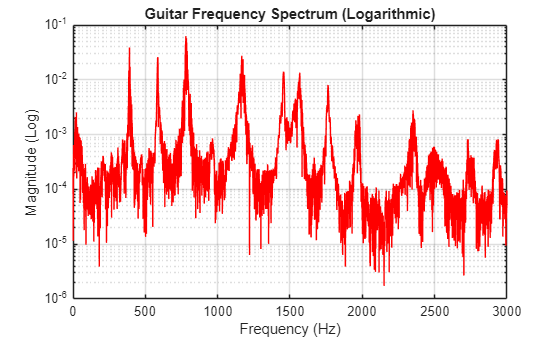


figure('Name', 'Guitar Frequency Spectrum (Logarithmic)');
semilogy(f_G, P1_G, 'r');
title('Guitar Frequency Spectrum (Logarithmic)');
xlabel('Frequency (Hz)'); ylabel('Magnitude (Log)');
xlim([0 3000]);
grid on;


% Update this string with the name and path of your actual .m4a audio file
filenameT = "C:\Users\user\Downloads\Tabla sound.m4a"; 

% Read the audio file
% 'Ts' is the amplitude data, 'Fst' is the sampling frequency (Hz)
[Ts, Fst] = audioread(filenameT);

% Convert Stereo to Mono (if necessary)
if size(Ts, 2) > 1
    Ts = mean(Ts, 2);
end

% Calculating the number of samples in Tabla
NT = length(Ts);

% Calculating the time of the instrument
% Since Fst is frequency, 1/Fst is the sampling period (dt)
TT = NT * (1/Fst);

fprintf('Length of Tabla recording: %.4f seconds\n', TT);

Length of Tabla recording: 5.9092 seconds


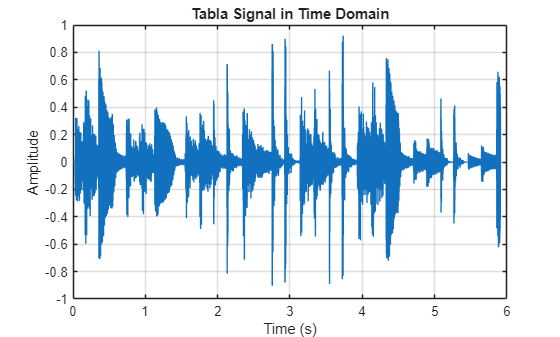


%% Part 2: Frequency Content Analysis

% Plotting the signals in Time Domain
figure('Name', 'Time Domain Signals');
plot((0:NT-1) * (1/Fst), Ts);
title('Tabla Signal in Time Domain');
xlabel('Time (s)'); ylabel('Amplitude'); grid on;

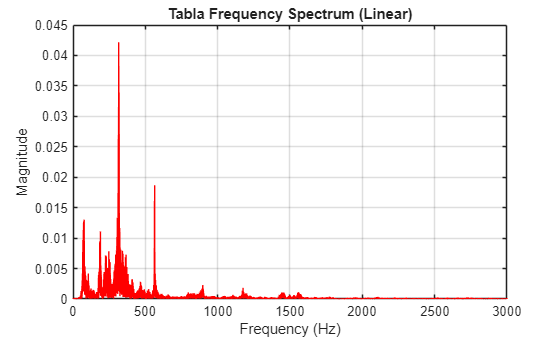


% --- Tabla FFT ---
% Fst is ALREADY the sampling frequency in Hz

% Creating a frequency vector for x axis 
f_T = Fst * (0:floor(NT/2)) / NT;

% Computing FFT (Fast Fourier Transform)
Y_T = fft(Ts);               

% Normalizing the signal and considering magnitude of the signal
P2_T = abs(Y_T / NT);           

% Converting the two sided signal into a single sided signal
P1_T = P2_T(1:floor(NT/2)+1);          
P1_T(2:end-1) = 2 * P1_T(2:end-1); 

% --- Plotting Tabla (Linear & Logarithmic) ---
figure('Name', 'Tabla Frequency Spectrum');
plot(f_T, P1_T, 'r');
title('Tabla Frequency Spectrum (Linear)');
xlabel('Frequency (Hz)'); ylabel('Magnitude');
xlim([0 3000]); % Zoom in to see the peaks clearly
grid on;

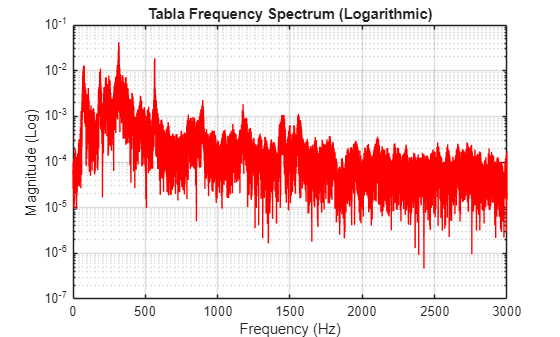


figure('Name', 'Tabla Frequency Spectrum (Logarithmic)');
semilogy(f_T, P1_T, 'r');
title('Tabla Frequency Spectrum (Logarithmic)');
xlabel('Frequency (Hz)'); ylabel('Magnitude (Log)');
xlim([0 3000]);
grid on;


% Update this string with the name and path of your actual audio file
filenameD = "C:\Users\user\Downloads\mixkit-piano-falling-effect-408.wav"; % Change to .m4a or .mp3 if needed


% Read the audio file
% 'Ds' is the amplitude data, 'Fsd' is the sampling frequency (Hz)
[Ds, Fsd] = audioread(filenameD);


% Convert Stereo to Mono (if necessary)
if size(Ds, 2) > 1
    Ds = mean(Ds, 2);
end


% Calculating the number of samples in Drum
ND = length(Ds);


% Calculating the time of the instrument
% Since Fsd is frequency, 1/Fsd is the sampling period (dt)
TD = ND * (1/Fsd);


fprintf('Length of Drum recording: %.4f seconds\n', TD);

Length of Drum recording: 2.1926 seconds


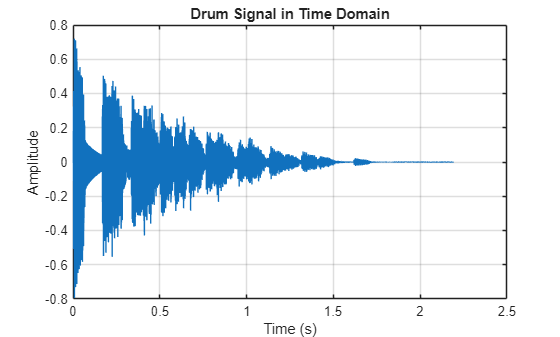



%% Part 2: Frequency Content Analysis


% Plotting the signals in Time Domain
figure('Name', 'Time Domain Signals');
plot((0:ND-1) * (1/Fsd), Ds);
title('Drum Signal in Time Domain');
xlabel('Time (s)'); ylabel('Amplitude'); grid on;

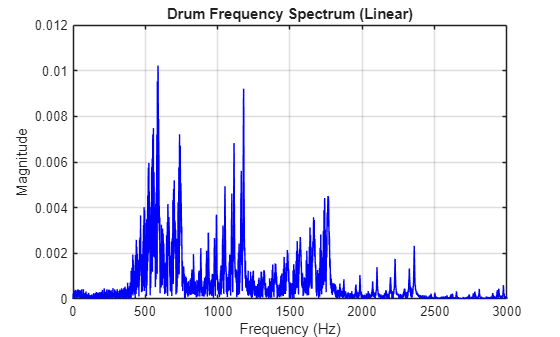



% --- Drum FFT ---
% Fsd is ALREADY the sampling frequency in Hz


% Creating a frequency vector for x axis 
f_D = Fsd * (0:floor(ND/2)) / ND;


% Computing FFT (Fast Fourier Transform)
Y_D = fft(Ds);               


% Normalizing the signal and considering magnitude of the signal
P2_D = abs(Y_D / ND);           


% Converting the two sided signal into a single sided signal
P1_D = P2_D(1:floor(ND/2)+1);          
P1_D(2:end-1) = 2 * P1_D(2:end-1); 


% --- Plotting Drum (Linear & Logarithmic) ---
figure('Name', 'Drum Frequency Spectrum');
plot(f_D, P1_D, 'b'); % Changed to blue just to easily distinguish from Tabla
title('Drum Frequency Spectrum (Linear)');
xlabel('Frequency (Hz)'); ylabel('Magnitude');
xlim([0 3000]); % Zoom in to see the peaks clearly
grid on;

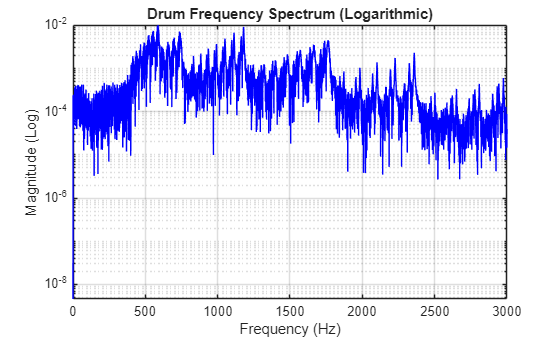



figure('Name', 'Drum Frequency Spectrum (Logarithmic)');
semilogy(f_D, P1_D, 'b');
title('Drum Frequency Spectrum (Logarithmic)');
xlabel('Frequency (Hz)'); ylabel('Magnitude (Log)');
xlim([0 3000]);
grid on;



% ==========================================
% 4. AUTOMATED PEAK DETECTION (KEYNOTE & OVERTONES)
% ==========================================

% We use P1_D (Drum single-sided spectrum) and f_D (Drum frequencies)
% Since drums are very noisy/percussive, you might need to adjust MinPeakHeight
[peaks_mag_D, peak_freqs_D] = findpeaks(P1_D, f_D, ...
                                    'MinPeakHeight', 0.005, ... 
                                    'MinPeakDistance', 50);

fprintf('\n--- Drum Peak Frequencies ---\n');


--- Drum Peak Frequencies ---


% Display the first 10 peaks
for i = 1:min(10, length(peak_freqs_D))
    fprintf('Peak %d: %.2f Hz\n', i, peak_freqs_D(i));
end

Peak 1: 524.50 Hz
Peak 2: 587.43 Hz
Peak 3: 736.57 Hz
Peak 4: 1113.30 Hz
Peak 5: 1179.43 Hz



% ==========================================
% 4. AUTOMATED PEAK DETECTION (KEYNOTE & OVERTONES)
% ==========================================

% We use P1_T (Tabla single-sided spectrum) and f_T (Tabla frequencies)
% Note: Percussive instruments like Tabla can have very messy frequency spectrums!
% You might need to adjust 'MinPeakHeight' or 'MinPeakDistance' heavily here.
[peaks_mag_T, peak_freqs_T] = findpeaks(P1_T, f_T, ...
                                    'MinPeakHeight', 0.005, ... 
                                    'MinPeakDistance', 50);

fprintf('\n--- Tabla Peak Frequencies ---\n');


--- Tabla Peak Frequencies ---


% Display the first 10 peaks
for i = 1:min(10, length(peak_freqs_T))
    fprintf('Peak %d: %.2f Hz\n', i, peak_freqs_T(i));
end

Peak 1: 77.34 Hz
Peak 2: 189.70 Hz
Peak 3: 247.58 Hz
Peak 4: 315.95 Hz
Peak 5: 366.72 Hz
Peak 6: 564.54 Hz


% ==========================================
% 4. AUTOMATED PEAK DETECTION (KEYNOTE & OVERTONES)
% ==========================================

% We use P1_G (Guitar single-sided spectrum) and f_G (Guitar frequencies)
% You may need to adjust 'MinPeakHeight' if your .wav recording is very quiet or loud
[peaks_mag_G, peak_freqs_G] = findpeaks(P1_G, f_G, ...
                                    'MinPeakHeight', 0.005, ... 
                                    'MinPeakDistance', 50);

fprintf('\n--- Guitar Peak Frequencies ---\n');


--- Guitar Peak Frequencies ---


% Display the first 10 peaks (The keynote + overtones)
for i = 1:min(10, length(peak_freqs_G))
    fprintf('Peak %d: %.2f Hz\n', i, peak_freqs_G(i));
end

Peak 1: 390.59 Hz
Peak 2: 585.54 Hz
Peak 3: 779.79 Hz
Peak 4: 1166.87 Hz
Peak 5: 1455.79 Hz
Peak 6: 1567.99 Hz
Peak 7: 1762.93 Hz


## EE251/CE252 Course Project - Task B Master Script


%% ========================================================================
% 1. DATA IMPORT & FFT COMPUTATION (Covers Task B, Part a)
% ========================================================================
disp('Processing Task A and Task B Audio Files...');

Processing Task A and Task B Audio Files...


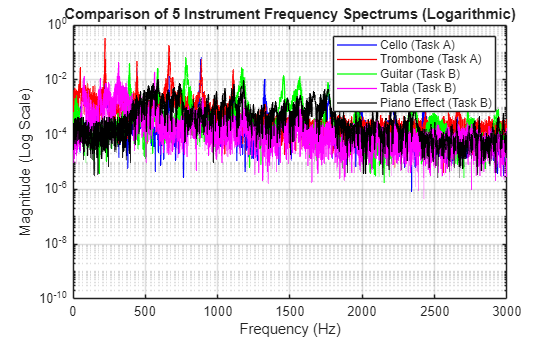


% --- Task A: Cello ---
Nc = length(cello.x); Y_cello = fft(cello.x);
P1_cello = abs(Y_cello / Nc); P1_cello = P1_cello(1:floor(Nc/2)+1); P1_cello(2:end-1) = 2 * P1_cello(2:end-1);
f_cello = (1/cello.dt) * (0:floor(Nc/2)) / Nc;

% --- Task A: Trombone ---
Nt = length(trombone.x); Y_trombone = fft(trombone.x);
P1_trombone = abs(Y_trombone / Nt); P1_trombone = P1_trombone(1:floor(Nt/2)+1); P1_trombone(2:end-1) = 2 * P1_trombone(2:end-1);
f_trombone = (1/trombone.dt) * (0:floor(Nt/2)) / Nt;

% --- Task B: Guitar ---
fileG = "C:\Users\user\Downloads\mixkit-musical-alert-notification-2309.wav"; 
[Gs, Fsg] = audioread(fileG);
if size(Gs, 2) > 1, Gs = mean(Gs, 2); end
NG = length(Gs); Y_G = fft(Gs);
P1_G = abs(Y_G / NG); P1_G = P1_G(1:floor(NG/2)+1); P1_G(2:end-1) = 2 * P1_G(2:end-1);
f_G = Fsg * (0:floor(NG/2)) / NG;

% --- Task B: Tabla ---
fileT = "C:\Users\user\Downloads\Tabla sound.m4a"; 
[Ts, Fst] = audioread(fileT);
if size(Ts, 2) > 1, Ts = mean(Ts, 2); end
NT = length(Ts); Y_T = fft(Ts);
P1_T = abs(Y_T / NT); P1_T = P1_T(1:floor(NT/2)+1); P1_T(2:end-1) = 2 * P1_T(2:end-1);
f_T = Fst * (0:floor(NT/2)) / NT;

% --- Task B: Piano Falling Effect ---
fileP = "C:\Users\user\Downloads\mixkit-piano-falling-effect-408.wav"; 
[Ps, Fsp] = audioread(fileP);
if size(Ps, 2) > 1, Ps = mean(Ps, 2); end
NP = length(Ps); Y_P = fft(Ps);
P1_P = abs(Y_P / NP); P1_P = P1_P(1:floor(NP/2)+1); P1_P(2:end-1) = 2 * P1_P(2:end-1);
f_P = Fsp * (0:floor(NP/2)) / NP;


%% ========================================================================
% 2. MULTI-SIGNAL SPECTRAL COMPARISON (Covers Task B, Part b)
% ========================================================================
% Plotting all 5 spectrums on a single logarithmic grid to show similarities 
% (keynote presence) and differences (overtone decay and noise floors).

figure('Name', 'Task B(b): 5-Instrument Spectral Comparison');
semilogy(f_cello, P1_cello, 'b', 'LineWidth', 1); hold on;
semilogy(f_trombone, P1_trombone, 'r', 'LineWidth', 1);
semilogy(f_G, P1_G, 'g', 'LineWidth', 1); 
semilogy(f_T, P1_T, 'm', 'LineWidth', 1); 
semilogy(f_P, P1_P, 'k', 'LineWidth', 1); 

title('Comparison of 5 Instrument Frequency Spectrums (Logarithmic)');
xlabel('Frequency (Hz)'); ylabel('Magnitude (Log Scale)');
xlim([0 3000]); % Limits strictly enforced for fair visual comparison
legend('Cello (Task A)', 'Trombone (Task A)', 'Guitar (Task B)', 'Tabla (Task B)', 'Piano Effect (Task B)');
grid on; hold off;



%% ========================================================================
% 3. ADDITIVE SYNTHESIS ALGORITHM (Covers Task B, Part c)
% ========================================================================
% Demonstrating how a synthesizer recreates sound artificially.
% We use the exact mathematical frequencies and magnitudes found in the Trombone 
% analysis as our digital blueprint.

Fs_synth = 44100;           % Standard DAC audio sampling rate
T_synth = 2;                % 2 seconds duration
t_synth = 0:(1/Fs_synth):(T_synth - 1/Fs_synth);

% Blueprint extracted from findpeaks (f0, k1, k2, k3, k4)
synth_freqs = [221.38, 441.88, 663.26, 885.53, 1106.91]; 
synth_mags  = [0.3284, 0.0481, 0.1797, 0.0571, 0.0232];  

artificial_sound = zeros(1, length(t_synth));

% Combining pure sine waves to rebuild the timbre
for i = 1:length(synth_freqs)
    artificial_sound = artificial_sound + synth_mags(i) * sin(2 * pi * synth_freqs(i) * t_synth);
end

% Normalize to prevent digital clipping
artificial_sound = artificial_sound / max(abs(artificial_sound));

% Play the synthesized sound (Uncomment to demonstrate during the viva!)
% disp('Playing Synthesized Trombone...');
% soundsc(artificial_sound, Fs_synth);


%% ========================================================================
% 4. SPECTRAL DETECTION SYSTEM (Covers Task B, Part d)
% ========================================================================
% Demonstrating how an algorithm identifies an instrument's presence.
% We will simulate feeding the Trombone signal into the detection logic to 
% see if it successfully triggers a match.

disp('--- Running Detection System ---');

--- Running Detection System ---



% 1. Define the mathematical "Fingerprint" of the target (Trombone)
target_f0 = 221.38; 
target_k2 = 663.26; % The trombone's distinctively loud 2nd overtone
tolerance = 2.0;    % +/- 2 Hz allowed for slight tuning offsets

% 2. Scan the incoming audio buffer (using findpeaks on the Trombone signal as a test)
[test_mags, test_freqs] = findpeaks(P1_trombone, f_trombone, 'MinPeakHeight', 0.05, 'MinPeakDistance', 50);

% 3. Logic Gate: Check if the scanned peaks contain the target fingerprint
is_match_f0 = any(abs(test_freqs - target_f0) <= tolerance);
is_match_k2 = any(abs(test_freqs - target_k2) <= tolerance);

if is_match_f0 && is_match_k2
    disp('DETECTION RESULT: Target Instrument (Trombone) matched and DETECTED.');
else
    disp('DETECTION RESULT: Target Instrument NOT detected.');
end

DETECTION RESULT: Target Instrument (Trombone) matched and DETECTED.
